clear

## evolution parameters

N=81;%波导数目
NN=2000;%步进次数
k1=0.8;
k2=0.8;%耦合系数
beta1=0;
beta2=0;%传播常数
dl=0.01;%步进大小

y=zeros(N,1);
y(38)=0.5;
y(39)=0.5;
y(40)=1;
y(41)=1;
y(42)=1;
y(43)=0.5;
y(44)=0.5;%基模

## evolution calc

offdiag1 = zeros(1,N);
offdiag1(1:2:N-1) = beta1;
offdiag1(2:2:N) = beta2;

offdiag2 = zeros(1,N-1);
offdiag2(1:2:N-1) = k1;
offdiag2(2:2:N-2) = k2;

H = zeros(N,N) + diag(offdiag1,0)+ diag(offdiag2,1) + diag(offdiag2,-1);

output=zeros(NN,N);
for temp=1:1:NN
    output(temp,:)=expm(-1*1i*H*temp*dl)*y;
end
OutputI = output.*conj(output);
figure(1);
imagesc(OutputI);

## gauss end face

将OutputI(end,:)各点扩大到二维高斯光斑

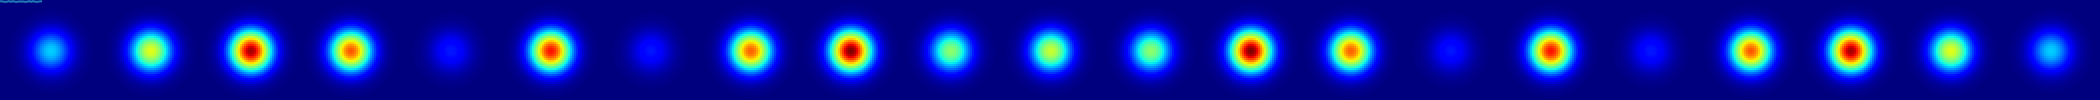

构建函数gaussModeField(A,x,y,wx,wy)，可实现在2x+1,2y+1大小的矩阵上，以A为峰值，wx、wy为束腰的高斯分布图，[0,0]点值为A。

最终调用gaussModeField赋值给输出图像

function Output = gaussModeField(A,x,y,wx,wy)

end

[Dx,Dy] = deal(50,50);
[wx,wy] = deal(Dx/4,Dy/4);
OutputIGauss = zeros(Dy*2+1,(Dx*2+1)*N);
for temp = 1:N
    A = OutputI(end,temp);
    OutputIGaussgn(:,((Dx*2+1)*(temp-1)+1):((Dx*2+1)*temp)) = gaussModeField(A,Dx,Dy,wx,wy);
end
figure(2);
imagesc(OutputIGaussgn);

## gauss propagation

同理为将各行的81个点拓展到一维高斯光斑